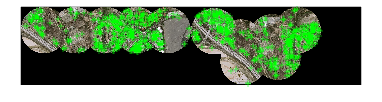

   576

   655



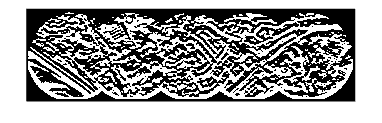

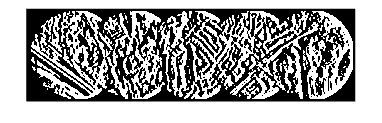

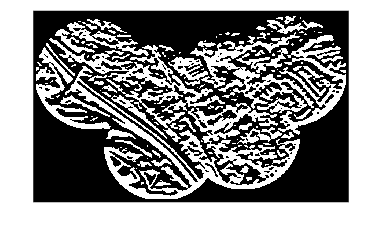

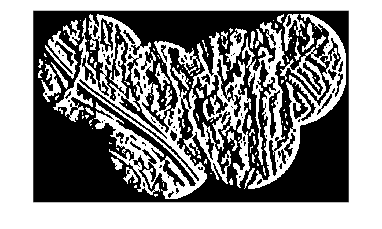

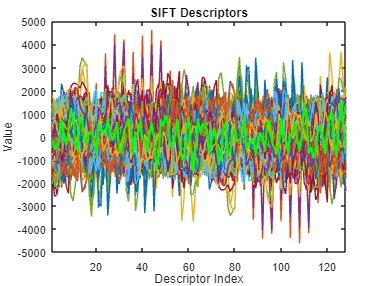

ans = 276

ans = 140

ans = 72

ans = 40

ans = 23

ans = 10

ans = 2

ans = 0

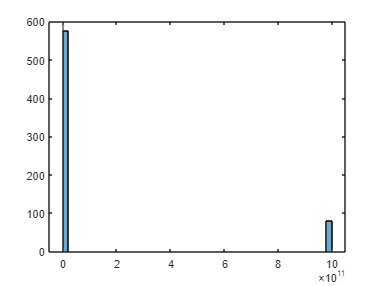

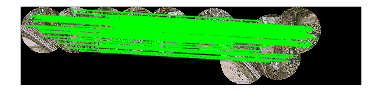

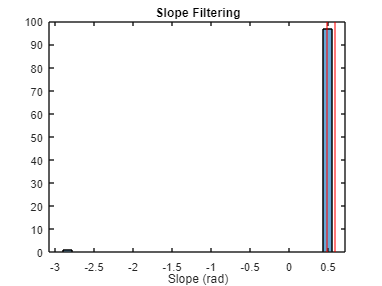

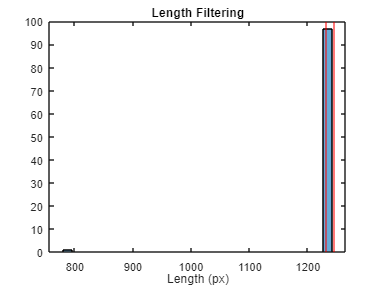

final_slope = 0

final_length = 0

final_delta_x = single
-132.1546

final_delta_y = single
-75.8866

final_confidence = 0.1667

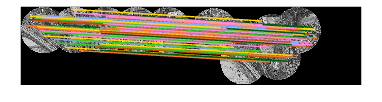

% right = imread("Test Images\Snipped\C\C2.png");
% left = imread("Test Images\Snipped\A\A6.png");
right = imread("Output\B\0.12541.png");
left = imread("Output\B\0.26466.png");
% right = imread("Test Images\Snipped\B\B11.png");
% left = imread("Output\B\0.9611.png");
% right = imread("Test Images\Snipped\A\A8.png");
% left = imread("Output\A\0.5827.png");

% right = imread("Test Images\Snipped\A\A7.jpg");
[final_slope, final_length, final_delta_x, final_delta_y, final_confidence] = custom_sift(left, right, 8, 1, false);

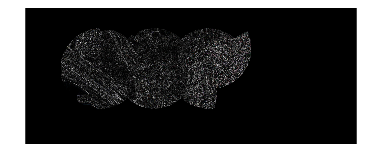

ans = 175536

ans =     4.5927
    4.5385
    4.5756


[out, valid] = merge_images(left, right, round(-final_delta_x), round(-final_delta_y),2, false);

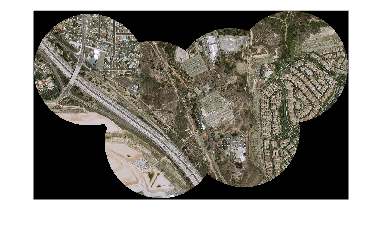

figure;
imshow(out)

% [a,b] = meshgrid(5,1:20)
% a = reshape(a,[],1);
% b = reshape(b,[],1);
% confidences = zeros(20,1);
% thresh = 0.008;
% for i=1:20
%     left = imread("Test Images\Snipped\B\B"+a(i)+".jpg");
%     right = imread("Test Images\Snipped\B\B"+b(i)+".jpg");
%     [final_slope, final_length, final_confidence] = custom_sift(left, right, 8, true);
%     confidences(i) = final_confidence;
%     if final_confidence>thresh
%         disp(string(a(i))+string(b(i)))
%         disp(final_confidence)
%     end
% end
% figure;
% bar(confidences)
% yline(thresh)